%% Define simulation parameters
rng('default'); rng(0) % set the random number generator's starting value
g=9.81;        % gravity acceleration constant
qc=1;          % power spectral density of white noise excitation
r=0.1;         % measurement noise variance
x0=[1.5;0];    % initial state (radian angle and angular velocity)
DT=0.01;       % time step size
nk=500;        % number of steps

%% Generate the track and the measurements
T=(1:nk)*DT;   % timestamps
X=zeros(1,nk); % preallocate
Y=NaN(1,nk);   % preallocate using not-a-number
x=x0;
m=5;           % number of time steps per measurement
for k=1:nk
    x=x+DT*[x(2);-g*sin(x(1))]+[0;sqrt(qc*DT)*randn];
    if ~rem(k,m)
        Y(k)=sin(x(1))+sqrt(r)*randn;
    end
    X(k)=x(1);
end

%% Define some common filter parameters
m0 = [1.6;0];       % slightly off from x0
P0 = 0.1*eye(2);
Q=[0 0;0 qc*DT];
R=r;

%% Run the filters and smoothers
filtername={'EKF','EKF2'};
GA={@GaussApproxEKF,@GaussApproxEKF2};
nf=length(filtername);
M1f=zeros(nf,nk);     M1s = zeros(nf,nk);
Mf=zeros(2,nk); Pf=zeros(2,2,nk);   % save for the smoother
for jf=1:nf
    m=m0; P=P0;
    for k=1:nk   % forward sweep (filter)
        [m,P]=gf_predict(m,P,@pendulum_f,Q,GA{jf});
        [m,P]=gf_update(m,P,Y(k),@pendulum_h,R,GA{jf});
        M1f(jf,k)=m(1);
        Mf(:,k)=m; Pf(:,:,k)=P;
    end
    rmse=sqrt(mean((X(1,:)-M1f(jf,:)).^2));
    disp(['RMS error for filter ' num2str(jf) ' is ' num2str(rmse)])
    
end

RMS error for filter 1 is 0.17992
RMS error for filter 2 is 0.24851


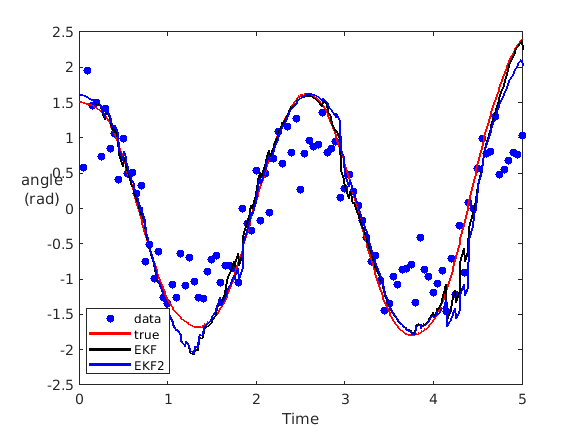


%% Plot the results
figure(1)
plot(T,Y,'b.', ...
    [0,T],[x0(1),X(1,:)],'r-',...
    [0,T],[m0(1),M1f(1,:)],'k-',...
    [0,T],[m0(1),M1f(2,:)],'b-','linewidth',2,'markersize',20);
xlabel('Time')
ylabel({'angle';'(rad)'},'rot',0)
legend('data','true',filtername{1},filtername{2},'location','SW')

function [mu,S,C]=GaussApproxEKF(m,P,g,E)
[mu,Gx]=g(m);
C=P*Gx';
S=Gx*C+E;
end

function [mu,S,C]=GaussApproxEKF2(m,P,g,E)
[mu,Gx,Gxx]=g(m);
C=P*Gx';
S=Gx*C+E;
n=size(E,1);
for i=1:n
    % GXX is a 3-dimensional array in the lecture; here it's a cell array
    mu(i)=mu(i)+0.5*trace(Gxx{i}*P);  
    for j=1:n
        S(i,j)=S(i,j)+0.5*trace(Gxx{i}*P*Gxx{j}*P);
    end
end
end

function [m,P]=gf_update(m,P,y,h,R,GaussApprox)
if ~isnan(y)
    [mu,S,C]=GaussApprox(m,P,h,R);
    K=C/S;
    P=P-K*S*K';
    m=m+K*(y-mu);
end
end

function [m,P]=gf_predict(m,P,f,Q,GaussApprox)
[m,P]=GaussApprox(m,P,f,Q);
end

function [f,Fx,Fxx]=pendulum_f(x)
DT=0.01; g=9.81;
f=x+DT*[ x(2)
    -g*sin(x(1))];
Fx=[1                DT
    -g*DT*cos(x(1))  1 ];
Fxx{1}=zeros(2,2);
Fxx{2}=[g*DT*sin(x(1)) 0
        0              0 ];
end

function [h,Hx,Hxx]=pendulum_h(x)
h=sin(x(1));
Hx=[cos(x(1)) 0];
Hxx{1}=[-sin(x(1))   0
          0          0];
end